# Coordinate Transformation and Lyapunov Stability for LTI Systems

## System Definition

Consider the following system in which two masses $m_1$ and $m_2$ are exchanging heat


$$m_1\dot{T}_1 = -a_1 T_1 + k_T (T_2 - T_1), \\
m_2\dot{T}_2 = -a_2 T_2 + k_T (T_1 - T_2) + u.$$
 

clear
close all
m1 = 1; m2 = 5; a1 = 1; a2=0.01; kT = 1;
Ac = [-(a1+kT)/m1 kT/m1; kT/m2 -(a2+kT)/m2], Bc = [0;1]

Ac =    -2.0000    1.0000
    0.2000   -0.2020


Bc =      0
     1


Discretize system using exact discretization

Ts = 1;
[A, B] = c2d(Ac,Bc,Ts)

A =     0.1630    0.3913
    0.0783    0.8665


B =     0.2669
    0.9250


C = eye(2); 
D = zeros(2,1);

## Coordinate Transformation

Eigenvalue decomposition $A = U \tilde{A} U^{-1}$

[U,At] = eig(A)

U =    -0.9945   -0.4652
    0.1045   -0.8852


At =     0.1218         0
         0    0.9076


Transform system using $\tilde{x} = T x = U^{-1}x$ 


$$\tilde{x}(k+1) = \tilde{A} \tilde{x}(k) + \tilde{B} u(k), \\
y(k) = \tilde{C} \tilde{x}(k) + \tilde{D} u(k).
$$


At = At; % = inv(U)*A*U
Bt = inv(U)*B; Ct = C*U; Dt =D;

Compare the two system using a step response test

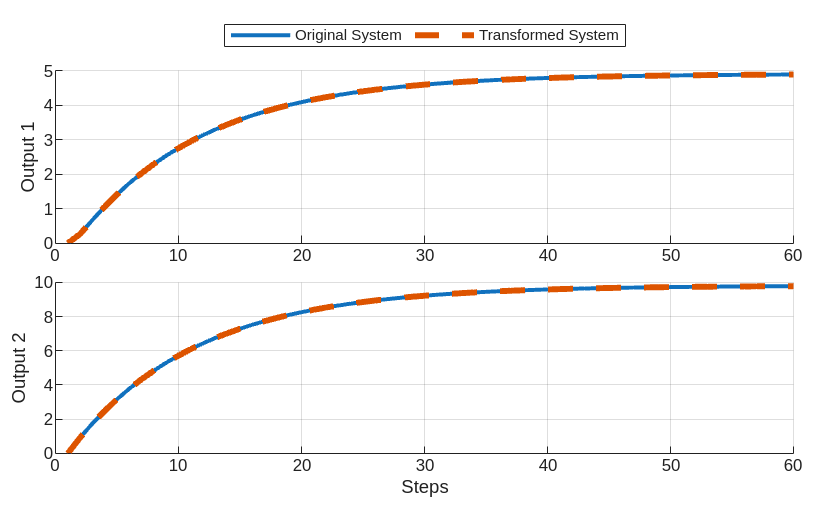

k = 60;         % number of time steps
x = [0; 0];     % init
xt = [0; 0];    % init
y = zeros(2,k);     % init
yt = zeros(2,k);    % init
u = 1;              % input
for i=2:k
    x = A*x+B*u;
    xt = At*xt+Bt*u;
    y(:,i) = C*x+D*u;
    yt(:,i) = Ct*xt+Dt*u;
end

% plot results
figure(1)
tiledlayout(2,1, Padding="compact", TileSpacing="compact")
lw1 = 2;
lw2 = 3;

nexttile
grid on
hold on
plot(y(1,:), LineWidth=lw1)
plot(yt(1,:), '--', LineWidth=lw2)
ylabel('Output 1')
legend({'Original System', 'Transformed System'}, Location="northoutside", NumColumns=2)

nexttile;
grid on
hold on
plot(y(2,:), LineWidth=lw1)
plot(yt(2,:), '--', LineWidth=lw2)
ylabel('Output 2')
xlabel('Steps')

% step(ss(A,B,C,D,Ts));
% step(ss(At,Bt,Ct,Dt,Ts))

Simplifies analysis of the autonymous system, e.g., when $u = 0$ or when $u = K x$ such that $x(k+1) = (A+BK)x(k)$. Instead of

x0 = [10; 0];   % initial condition
k = 10;         % number of time steps
x = x0;
for i=1:k
    x = A*x;
end
yk = C*x

yk =     0.1986
    0.3779


we can directly compute the output as $y(k) = \tilde{C} \tilde{A^{k}} \tilde{x}(0)$

xt0 = inv(U)*x0;    % transformed initial condition
ykt = Ct*At.^k*xt0  % direct computation of the output

ykt =     0.1986
    0.3779


## Convergence of Quadratic Cost

Choose cost function $Q$ 

Q = eye(2);

Exact infinite horizon cost is given by Lyapunov solution

P = dlyap(A',Q);

Compute running cost $q(i) = \sum_{k=0}^i x(k)^T Q x(k)$ for large $i$ 

x(:,1) = [0;sqrt(1/P(2,2))];    % initial state
q(1) = x(:,1)'*Q*x(:,1);        % initial state cost
for i = 1:50
    x(:,i+1) = A*x(:,i);
    q(i+1) = q(i) + x(:,i+1)'*Q*x(:,i+1);
end
q_sum = q(end);
p_exact = x(:,1)'*P*x(:,1);
p_bound = max(eig(U'*Q*U))*x(:,1)'*x(:,1)/(1-max(eig(A))^2);
q_sum, p_exact, p_bound

q_sum = 0.9999

p_exact = 1

p_bound = 1.2318

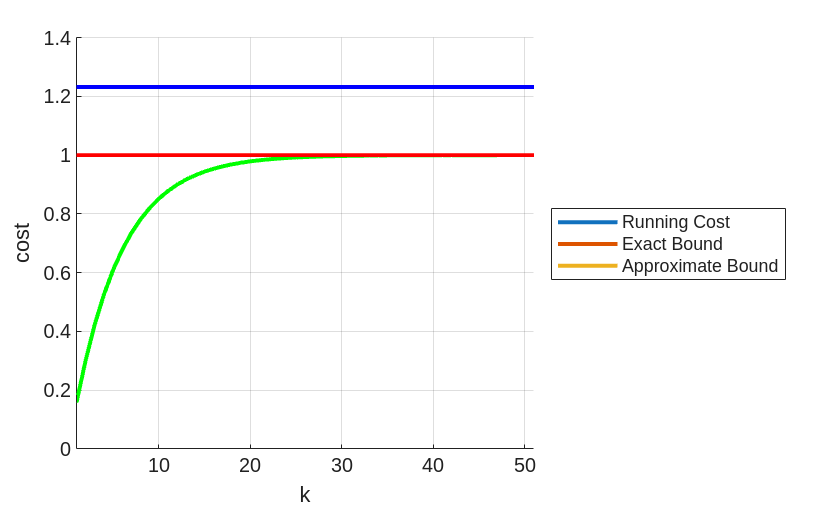

figure(2)
lw = 2;
hold on
grid on
plot(q, LineWidth=lw, Color='g')
plot([1, size(q,2)],[p_exact, p_exact], LineWidth=lw, Color='r');
plot([1, size(q,2)],[p_bound, p_bound], LineWidth=lw, Color='b');
xlim([1, size(q,2)])
xlabel('k'), ylabel('cost')
legend({'Running Cost','Exact Bound','Approximate Bound'}, Location="eastoutside")